# **Matlab案例代码解析**

## 2. 典型绘图案例

### 2.2 二维绘图

#### 2.2.8 旋转多边形

颜值即正义；

**颜色模板参考：**[**60套优雅的颜色模板**](https://zhuanlan.zhihu.com/p/444970597)

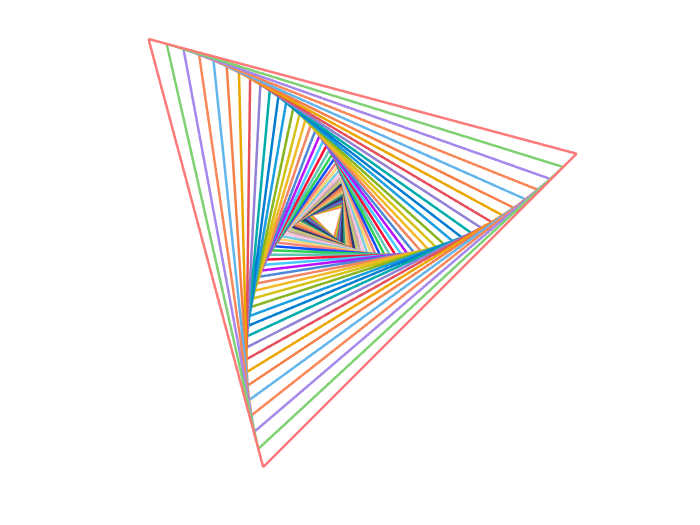

clear;clc;close all;
% 获取到颜色
[all_themes, all_colors] = GetColors();
m = 3;
n = 41;
d_angle = 2.25;
rotate = 45;
shift = [0, 0];
figure
SpiralPolygon(m, n, d_angle, rotate, shift, all_colors, 1.5);
colormap(all_themes{1});

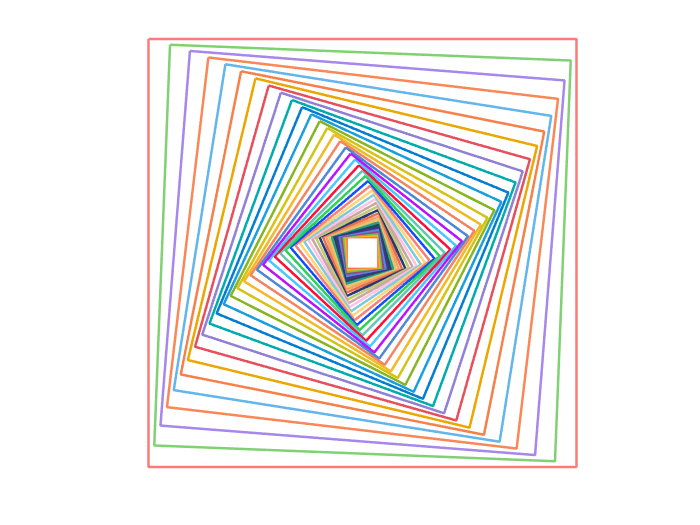

m = 4;
figure
SpiralPolygon(m, n, d_angle, rotate, shift, all_colors, 1.5);

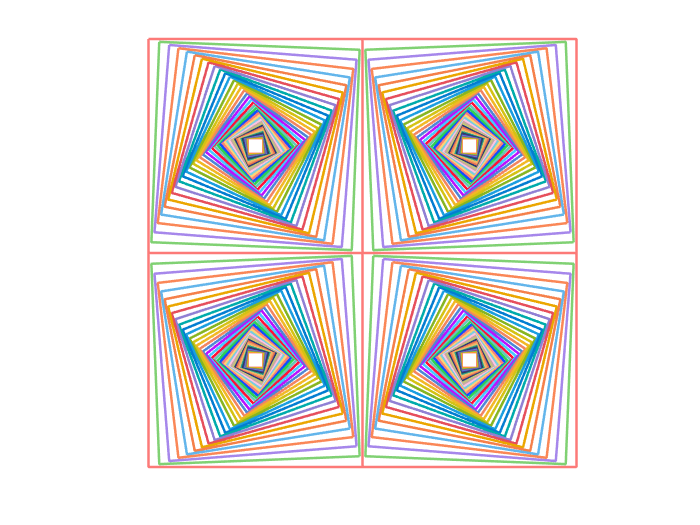

figure;
V = SpiralPolygon(m, n, -d_angle, rotate, shift, all_colors, 1.5);
hold on
dx = max(V(1, :)) - min(V(1, :));
dy = max(V(2, :)) - min(V(2, :));
shift = [dx, 0];
SpiralPolygon(m, n, d_angle, rotate, shift, all_colors, 1.5);
shift = [dx, dy];
SpiralPolygon(m, n, -d_angle, rotate, shift, all_colors, 1.5);
shift = [0, dy];
SpiralPolygon(m, n, d_angle, rotate, shift, all_colors, 1.5);
hold off